# DISKRET STOKASTISK

## 

## Generelt

**Summen af alle værdier skal give 1**

## Eksempel 1

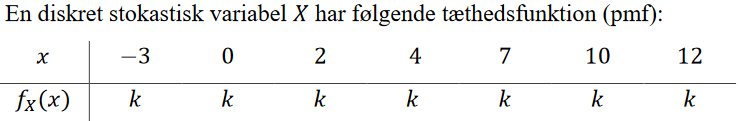

I dette tilælde giver alle værdier af X k. Derfor er k = 1/N, hvor N er antallet af diskrete værdier

clearvars
k = 1/7

k = 0.1429

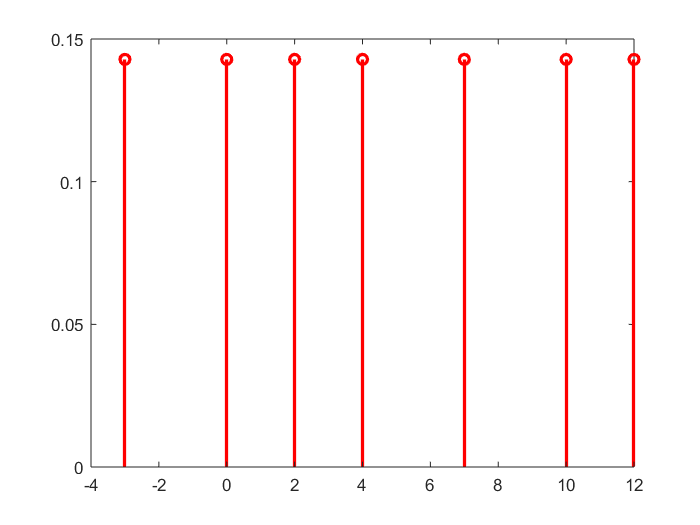

x = [-3, 0, 2, 4, 7, 10, 12];
y = [k, k, k, k, k, k, k];
stem(x,y,'-r','LineWidth',2)

## Eksempel 2

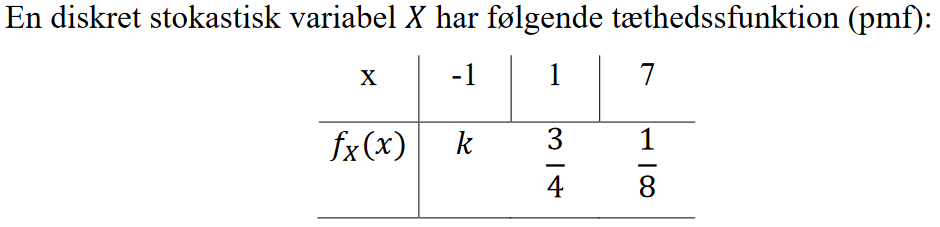

Da summen af alle værdier af f(x) skal give 1 findes k med:

k = 1 - (3/4) - (1/8)

k = 0.1250

# KONTINUER STOKASTISK

## 

## Generelt

PDF er gyldig når integralet fra minus uendelig til plus uendelig = 1

OG alle værdier af pdf er størrere eller lig 0

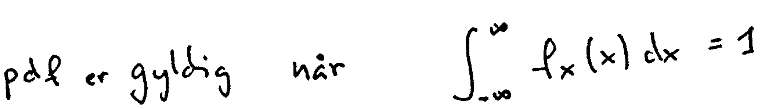

## Eksempel 1

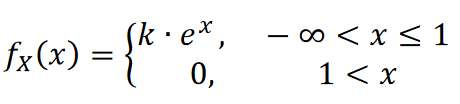

clearvars
syms x k
fun1 = k*exp(x);
fun2 = 0

fun2 = 0

% Gyldig når integralet af fun1 + fun2 = 1
% Integralet af 0 = 0
F = int(fun1,'x',-inf, 1) % Integrer fun1 i forhold til x, fra -uendelig til 1

$$F = k\,\mathrm{e}$$

k = solve(F==1, k) % k = 1/e

$$k = {\mathrm{e}}^{-1}$$

## Eksempel 2

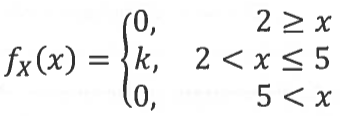

clearvars
close all
% Værdier 2 eller under = 0
% Værdier over 5 = 0
% Integralet af k fra 2 til 5 skal derfor være lig 0
syms k x
fun = k;
F = int(fun,'x', 2, 5);
k = solve(F==1, k)

$$k = \frac{1}{3}$$

%plot
y1 = piecewise(2>=x,0,2<x<=5,k,5<x,0)

$$y1 = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 2\\ \frac{1}{3} & \text{ if }x\in \left(2,5\right]\\ 0 & \text{ if }5<x \end{array}\right.$$

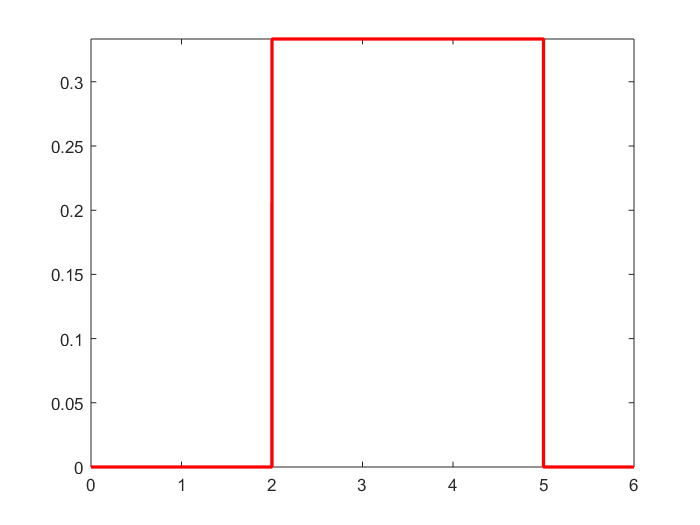

fplot(y1,[0,6], '-r','LineWidth',2)